首先给定需要进行近似计算的微分方程.


$$\left\lbrace \begin{array}{ll}
D_t u-{aD}_x^2 u=f\left(x,t\right), & x\in \left(0,1\right),t\in \left(0,1\right),\\
t=0,u=\exp \left(x\right)\sin \left(\frac{1}{2}\right), & x\in \left\lbrack 0,1\right\rbrack ,\\
u\left(0,t\right)=\sin \left(\frac{1}{2}-t\right),u\left(1,t\right)=\exp \left(1\right)\sin \left(\frac{1}{2}-t\right), & t\in \left\lbrack 0,1\right\rbrack \ldotp 
\end{array}\right.$$


其唯一的精确解为$u(x,t)=\exp(x)\sin(\frac{1}{2}-t).$

将微分方程作差分近似为


$$\left\lbrace \begin{array}{ll}
D_t^{+} u_j^k -{a{\delta_x}}^2 u_j^k =f\left(x_j ,t_k \right), & j=1:J-1,k=0:K-1,\\
 u_{j}^{0}=\exp(x)\sin(\frac{1}{2}),& j=0:J,\\
 u_{0}^{k}=\sin(\frac{1}{2}-t_{k}),u_{J}^{k}=\exp(1)\sin(\frac{1}{2}-t_{k}),&k=1:K.
\end{array}\right.$$


这里我习惯用


$${\bf\it u}^{0}=\varphi(x),{\bf\it u}_{0}=\psi_{1}(t),{\bf\it u}_{J}=\psi_{2}(t).$$


其按时间逐层计算的迭代式为


$$$$
u_{j}^{k+1}=(1-2r)u_{j}^{k}+r(u_{j+1}^{k}+u_{j-1}^{k})+\tau f(x_{j},t_{k}),r=a\tau h^{-2}\leq \frac{1}{2},j=1:J-1.
$$$$


作为边界的第$0$层和第$J$层将预先使用边界条件计算.

clear
%iteration parameters
K=100;
J=5;
tau=1/K;
h=1/J;
u=zeros(J+1,K+1);
varphi=@(x)exp(x)*sin(1/2);
psi1=@(t)sin(1/2-t);
psi2=@(t)exp(1)*sin(1/2-t);
f=@(x,t)-exp(x)*(cos(1/2-t)+2*sin(1/2-t));
a=2;
r=a*tau/(h^2);

开始初值赋予

k_=@(x)x+1;
j_=@(x)x+1;
for j_c=0:J
    j=j_c+1;
    u(j,k_(0))=varphi(j_c*h);
end
for k_c=0:K
    k=k_c+1;
    u(j_(0),k)=psi1(k_c*tau);
    u(j_(J),k)=psi2(k_c*tau);
end

显式循环计算

for k_c=0:K-1
    k=k_c+1;
    for j_c=1:J-1
        j=j_c+1;
        u(j,k+1)=r*u(j-1,k)+(1-2*r)*u(j,k)+r*u(j+1,k)+tau*f(j_c*h,k_c*tau);
    end
end

储存网格上的精确解

u_ESM=zeros(J+1,K+1);
u_ES=@(x,t)exp(x)*sin(1/2-t);
for k_c=0:K
    k=k_c+1;
    for j_c=0:J
        j=j_c+1;
        u_ESM(j,k)=u_ES(j_c*h,k_c*tau);
    end
end

绘图

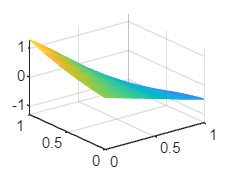

X=tau*(0:K);
T=h*(0:J);
mesh(X,T,u)

%mesh(tau*(0:K),h*(0:J),u_ESM)

显示$r$和最大误差

disp(r)

    0.5000



disp(max(abs(u-u_ESM),[],'all'))

   5.2714e-04



## 向后差分

将微分方程作差分近似为


$$\left\lbrace \begin{array}{ll}
D_t^{-} u_j^k -{a{\delta_x}}^2 u_j^k =f\left(x_j ,t_k \right), & j=1:J-1,k=1:K,\\
 u_{j}^{0}=\exp(x)\sin(\frac{1}{2}),& j=0:J,\\
 u_{0}^{k}=\sin(\frac{1}{2}-t_{k}),u_{J}^{k}=\exp(1)\sin(\frac{1}{2}-t_{k}),&k=1:K.
\end{array}\right.$$


对于向后差分格式,其迭代格式为


$$\left\lbrace \begin{array}{ll}
-{\textrm{ru}}_{j-1}^k +\left(1+2r\right)u_j^k -{\textrm{ru}}_{j+1}^k =u_j^{k-1} +\tau f\left(x_j ,t_k \right), & j=1:J-1,k=1:K,\\
u_j^0 =\varphi \left(x_j \right), & j=0:J,\\
u_0^k =\psi_1 \left(t_k \right),u_J^k =\psi_2 \left(t_k \right), & k=0:K\ldotp 
\end{array}\right.$$


用矩阵形式表达,即为


$${\bf\it A}:={\rm tridiag}(1+2r,-r,-r),\\
{\bf\it A}{\bf\it u}^{k+1}={\bf\it u}^{k}+\tau {\bf\it f}^{k}+r({\bf\it E}_{1,1}{{\bf\it \psi}_1}^{k}+{\bf\it E}_{K+1,K+1}{{\bf\it \psi}_2}^{k}).$$


重新赋予参数初值.

J=1000;
K=1000;
tau=1/K;
h=1/J;
r=a*tau/(h^2);

创建三对角矩阵$\bf\it A$,以及数值储存矩阵.

A=diag((1+2*r)*ones([1,J+1]))+diag((-1*r)*ones([1,J]),-1)+diag((-1*r)*ones([1,J]),1);
u_after=zeros(J+1,K+1);
f_after=zeros(J+1,K+1);

初值赋予

for j_c=0:J
    j=j_c+1;
    u_after(j,k_(0))=varphi(j*h);
end
for k_c=0:K
    k=k_c+1;
    u_after(j_(0),k)=psi1(k_c*tau);
    u_after(j_(J),k)=psi2(k_c*tau);
end

非齐次项矩阵数值赋予

for k_c=0:K
    k=k_c+1;
    for j_c=0:J
        j=j_c+1;
        f_after(j,k)=f(j_c*h,k_c*tau);
    end
end

开始迭代循环

%{
另外一种是考虑到初值已经被赋予了,所以可以减少循环层,
但我认为这是不必要的,虽然我还是将这个代码写出来,
并且它运行的很好.
%}
%{
temp=zeros(J-1,K-1);
for k_c=0:K
    k=k_c+1;
    temp(1,k)=r*psi1(k_c*tau);
    temp(end,k)=r*psi2(k_c*tau);
end

A_J=A(j_(1):j_(J-1),j_(1):j_(J-1));
for k_c=0:K-1
    k=k_c+1;
    u_after(2:J,k+1)=A_J\(u_after(2:J,k)+tau*f_after(2:J,k)+temp(:,k));
end
%}
temp=zeros(J+1,K+1);
for k_c=0:K
    k=k_c+1;
    temp(1,k)=r*psi1(k_c*tau);
    temp(end,k)=r*psi2(k_c*tau);
end
for k_c=0:K-1
    k=k_c+1;
    u_after(:,k+1)=A\(u_after(:,k)+tau*f_after(:,k)+temp(:,k));
end

最大误差显示

u_ESM=zeros(J+1,K+1);
for k_c=0:K
    k=k_c+1;
    for j_c=0:J
        j=j_c+1;
        u_ESM(j,k)=u_ES(j_c*h,k_c*tau);
    end
end
disp(max(abs(u_after-u_ESM),[],'all'))

    0.0037



绘图

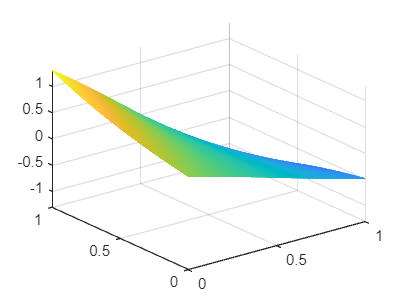

mesh(tau*(0:K),h*(0:J),u_after(1:end,1:end))

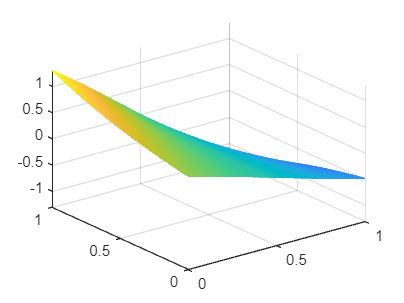

mesh(tau*(0:K),h*(0:J),u_ESM(1:end,1:end))